# OT-RMC-SA Taxonomy and Sample Classification

We first load the Mosek Matlab package. 

addpath C:/Users/sebastian/Mosek/10.2/toolbox/r2017a

Load the formatted Baron Pancreas dataset:

load baronpc ; 
dim = 50; %number of PCs
numPat = length(stride); %number of samples in dataset
celltypes= unique(cellnames); %unique cell types present in dataset 
numcells = length(celltypes); %number of unique cell types.

We now apply the OT-RMC algorithm for each sample. The output for a sample is a similarity matrix with respect to the clusters present in that sample. 

lambda2=0;
lambda = .075;
matchSelf = cell(numPat,1);
for i =1:numPat
    nclust=stride(i); %number of clusters in sample i
    start = sum(stride(1:i-1))+1;
    ms = supp(1:dim,start:start+nclust-1); %mean vectors of clusters in sample i
    vars = supp(dim+1:dim^2+dim,start:start+nclust-1); %cov matrices of clusters in sample i
    p = ww(start:start+nclust-1);%proportions of clusters in sample i
    cost = CostMat(ms,ms,vars,vars,nclust,nclust); %compute cost matrix
    cost = real(cost/max(cost,[],"all"));  %standardize
    [~,res]=otrmcl1(cost,lambda,lambda2,p,p); %apply OTRMC
    xx=res.sol.itr.xx; 
    gammaij=reshape(xx(nclust+nclust+1:nclust+nclust+nclust*nclust),[nclust,nclust]); %weight matrix
    %row and vector standardization
    gammaijcol =  gammaij./ max(abs(gammaij), [], 1);
    gammaijrow =  gammaij./ max(abs(gammaij), [], 2);
    matchSelf{i} = (gammaijcol+gammaijrow)/2;
end

MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86



We compute the matching matrices for the different pairwise sample combinations. For each pair of samples we obtain a similarity matrix 

combs = nchoosek(1:numPat,2);
matchM = cell(length(combs),1);
for i=1:length(combs)
    nclust1=stride(combs(i,1));  %number of clusters in 1st sample 
    nclust2=stride(combs(i,2));  %number of clusters in 2nd sample 
    start1 = sum(stride(1:combs(i,1)-1))+1;   %how many columns to ignore +1 
    start2 = sum(stride(1:combs(i,2)-1))+1;
    ms1 = supp(1:dim,start1:start1+nclust1-1); %mean vectors of clusters in first sample
    ms2 = supp(1:dim,start2:start2+nclust2-1);
    vars1=supp(dim+1:dim+dim^2,start1:start1+nclust1-1); %cov matrices of clusters in first sample
    vars2 = supp(dim+1:dim+dim^2,start2:start2+nclust2-1);
    p1 = ww(start1:start1+nclust1-1);  %proportions of clusters in sample 1
    p2 = ww(start2:start2+nclust2-1);
    cost = CostMat(ms1,ms2,vars1,vars2,nclust1,nclust2); %cost matrix computation
    cost = real(cost/max(cost,[],"all"));
    [~,res]=otrmcl1(cost,lambda,lambda2,p1,p2);  %apply OT-RMC
    xx=res.sol.itr.xx;
    gammaij=reshape(xx(nclust1+nclust2+1:nclust1+nclust2+nclust1*nclust2),[nclust1,nclust2]);
    %row and vector standardization
    gammaijcol =  gammaij./ max(abs(gammaij), [], 1);
    gammaijrow =  gammaij./ max(abs(gammaij), [], 2);
    matchM{i} = (gammaijcol+gammaijrow)/2;
end

MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86


MOSEK Version 10.2.5 (Build date: 2024-9-17 14:14:12)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86



We  now combine all of the different matching matrices into one big matching matrix, $\mathit{\mathbf{B}}$. We refer to $\mathit{\mathbf{B}}$ as the overall cluster similarity matrix.

Biggammaij = blkdiag(matchSelf{:}); % this functions takes a finite  list of matrices 
                                    % and creates a larger matrix witht the
                                    % matrices as diagonal blocks. {:}
                                    % spits out all the matrices from the
                                    % cell array
startPat=1;
endPat = numPat-1;
for j =1:(numPat-1)
    nclust1=stride(j);  %number of clusters for individual j
    start1 = sum(stride(1:j-1))+1;   %how many columns to ignore +1
    endClust=start1+nclust1-1;
    Biggammaij(start1:endClust,endClust+1:end)=Biggammaij(start1:endClust,endClust+1:end)+ [matchM{startPat:endPat}];
    Biggammaij(endClust+1:end,start1:endClust)=Biggammaij(endClust+1:end,start1:endClust)+ [matchM{startPat:endPat}]';
    startPat = endPat+1;
    endPat = startPat+numPat-2-j;
end
%We bound below very small values in the large matrix:
Biggammaij(abs(Biggammaij) < min(ww)* 1E-7) = min(ww)* 1E-7;

## Dendrogram

We now need to transform $\mathbf{B}$ into a symmetric matrix $\mathbf{A}$. 


%Now we will create a distance matrix
A = real(-log(Biggammaij));
A= A/ max(max(A));
B = squareform(A);
tree=linkage(B,'ward'); 
cellClusters=cluster(tree,"MaxClust", numcells);

We build the dendrogram from the tree.

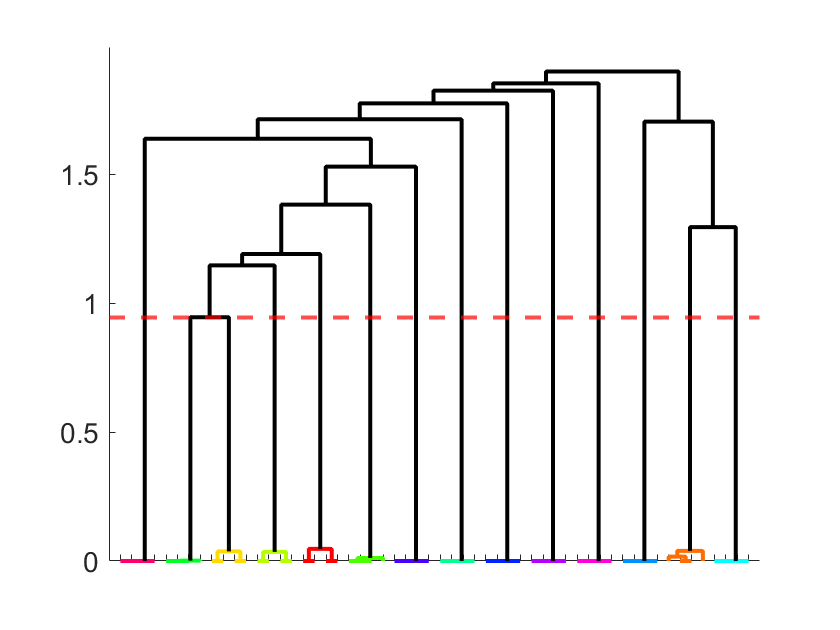

cutoff = max(tree(end-numcells+2, 3)); % Determine the cutoff height
figure;
H = dendrogram(tree, 0,'ColorThreshold', cutoff);
set(H, 'LineWidth', 2);
set(gca, 'FontSize', 14)
yline(cutoff, 'r--', 'LineWidth', 2); % Add the horizontal line
set(gca, 'XTickLabel', []);